## 创建50个城市点的数据集

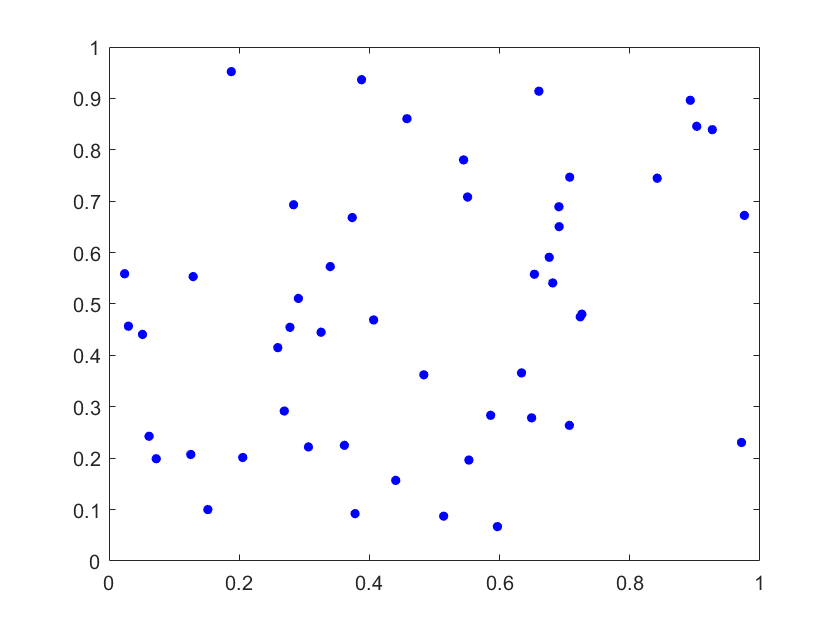

clc;
clf;
clear;

rng(3, 'twister');
cities = rand(2,50);
plot(cities(1, :), cities(2, :), 'b.', 'MarkerSize', 16, 'LineWidth',2);

% axis([-0.2, 1.2, -0.2, 1.2]);
save("50_cities.mat", "cities");

## 使用自己编写的模拟退火法进行求解

load("50_cities.mat")
temprature = 1e4;
temprature_min = 1e-6;
episodes = 20;
episode_length = 1e5;

multi_swap = 1;
trajectory_old = cities;
tic;
[trajectory_new, dist, temprature, exit_flag] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
toc;

时间已过 27.127807 秒。


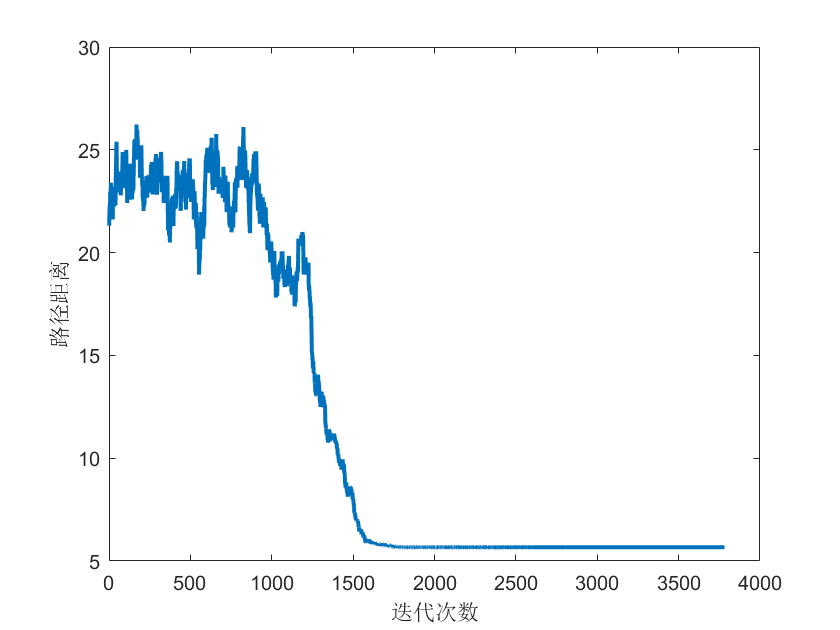

clf;
plot(dist, 'Linewidth', 2);
xlabel('迭代次数');
ylabel('路径距离');

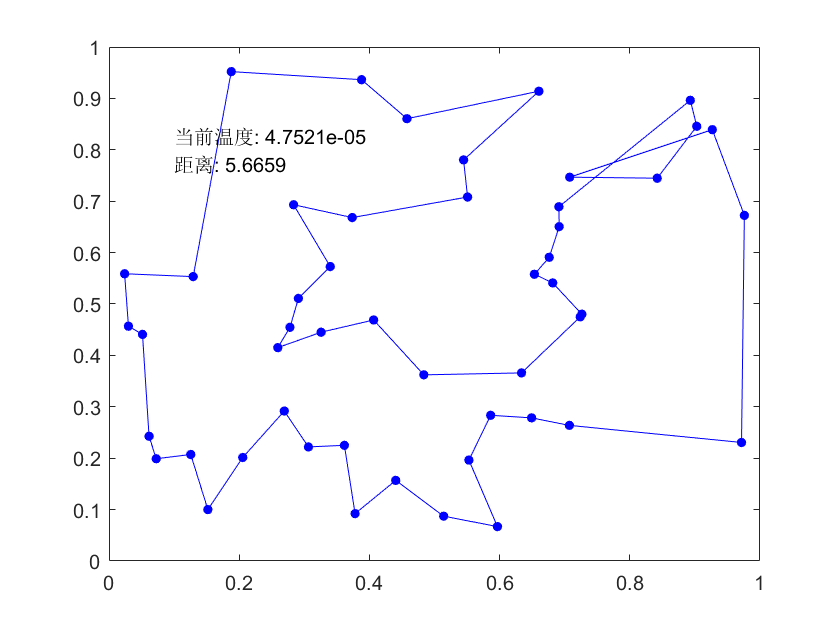


clf;
plot_trajectory(trajectory_new);
hold on;
text(0.1, 0.9, {['当前温度: ', num2str(temprature)];['距离: ', num2str(dist(end))]});

save("50_results.mat", "trajectory_new");


## 统计分析模拟退火法的收敛性质

load("50_cities.mat")
temperature_init = 1e4;
temprature_min = 1e-6;
episodes = 20;
episode_length = 1e4;
multi_swap = 1;

total = 100;        % 统计500次实验

dists = [];                         % 记录每次实验中的路径变化情况
final_dists =zeros(1, total);       %记录最后求解得到的路径长度
final_temerature = zeros(1, total);
time_cost = zeros(1, total);
iteration = zeros(1, total);
for i=1:total
    temprature = temperature_init;
    trajectory_old = cities;
    tic;
    [~, dist, temprature, ~] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
    toc;
    
    time_cost(i) = toc;
    final_dists(i) = dist(end);
    iteration(i) = length(dist);
    final_temerature(i) = temprature;
    
    % 添加一行新的迭代下降曲线
    if i==1
        dists = dist;
        continue;
    end
    
    len_old = size(dists, 2);
    len_new = size(dist, 2);
    if len_old < len_new
        dists(:, len_old:len_new) = repmat(dists(:, end),1, len_new-len_old+1);
    else
        dist(:, end:len_old) = dist(end);
    end
    dists = [dists; dist];
    
    
end

时间已过 2.732421 秒。
时间已过 2.695032 秒。
时间已过 2.637314 秒。
时间已过 2.698991 秒。
时间已过 2.668032 秒。
时间已过 2.673974 秒。
时间已过 2.610700 秒。
时间已过 2.706161 秒。
时间已过 2.691748 秒。
时间已过 2.648625 秒。
时间已过 2.661158 秒。
时间已过 2.624304 秒。
时间已过 2.658721 秒。
时间已过 2.655198 秒。
时间已过 2.669173 秒。
时间已过 2.638241 秒。
时间已过 2.624846 秒。
时间已过 2.684778 秒。
时间已过 2.612126 秒。
时间已过 2.645598 秒。
时间已过 2.701386 秒。
时间已过 2.619395 秒。
时间已过 2.630171 秒。
时间已过 2.677033 秒。
时间已过 2.639496 秒。
时间已过 2.626641 秒。
时间已过 2.623970 秒。
时间已过 2.725462 秒。
时间已过 2.612864 秒。
时间已过 2.637743 秒。
时间已过 2.618536 秒。
时间已过 2.679881 秒。
时间已过 2.653101 秒。
时间已过 2.654588 秒。
时间已过 2.665994 秒。
时间已过 2.749812 秒。
时间已过 2.640342 秒。
时间已过 2.679819 秒。
时间已过 2.710761 秒。
时间已过 2.659151 秒。
时间已过 2.635067 秒。
时间已过 2.809266 秒。
时间已过 2.768090 秒。
时间已过 2.739473 秒。
时间已过 2.645102 秒。
时间已过 2.627718 秒。
时间已过 2.701639 秒。
时间已过 2.608219 秒。
时间已过 2.709947 秒。
时间已过 2.622971 秒。
时间已过 2.676399 秒。
时间已过 2.710253 秒。
时间已过 2.786480 秒。
时间已过 2.656895 秒。
时间已过 2.651762 秒。
时间已过 2.744652 秒。
时间已过 2.708855 秒。
时间已过 2.737439 秒。
时间已过 2.692225 

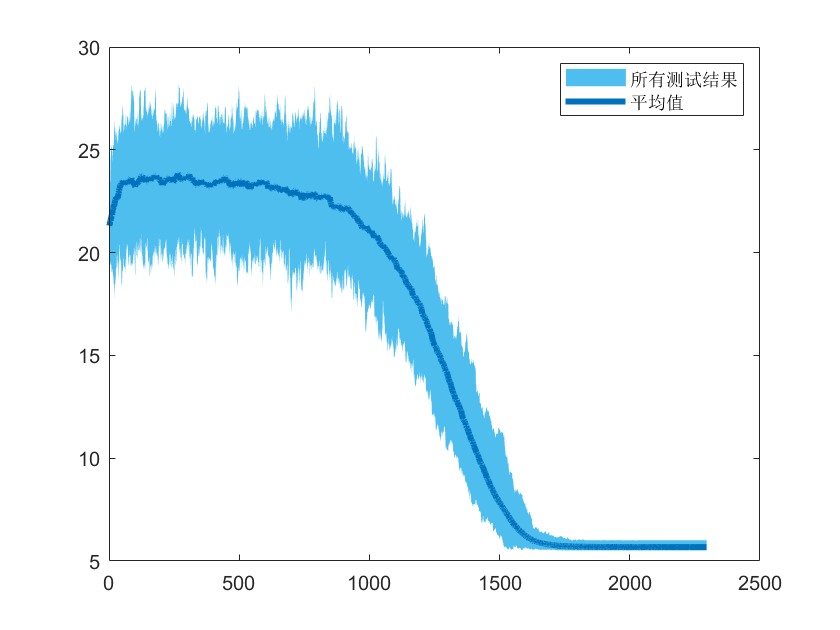

clf;
y = mean(dists, 1);
x = 1:1:length(y);
x_conf = [x, x(end:-1:1)];
y_conf = [min(dists,[], 1), flip(max(dists,[], 1))];
p = fill(x_conf,y_conf,'b','FaceColor',[0.3010 0.7450 0.9330],'EdgeColor','none');
hold on;
plot(x,y,'-', 'LineWidth',3,"Color",[0 0.4470 0.7410]);
legend('所有测试结果','平均值');

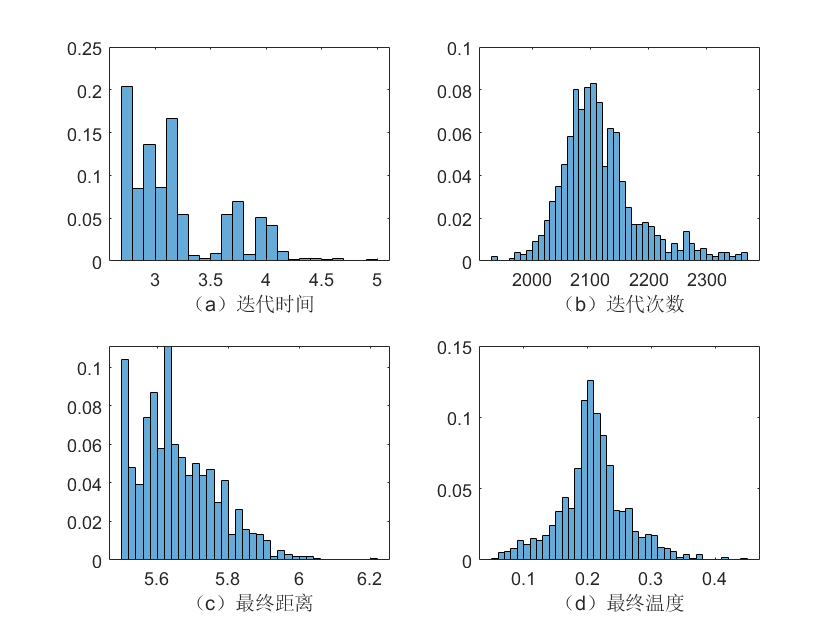

load('statics.mat');

clf;
subplot(221);
h1 = histogram(time_cost);
xlabel('（a）迭代时间');

subplot(222);
h2 = histogram(iteration);
xlabel('（b）迭代次数');

subplot(223);
h3 = histogram(final_dists);
xlabel('（c）最终距离');

subplot(224);
h4 = histogram(final_temerature);
xlabel('（d）最终温度');

h1.Normalization = 'probability';
h1.BinWidth = 0.1;
h2.Normalization = 'probability';
h2.BinWidth = 10;
h3.Normalization = 'probability';
h3.BinWidth = 0.02;
h4.Normalization = 'probability';
h4.BinWidth = 0.01;

## 使用别人的求解器

% load("100_cities.mat");
load x500.mat;
cities_ = cityXY';
tic;
[sortedCities, ~, ~] = solveTSP_benchmark( cities_, false );
toc;

时间已过 1.292529 秒。


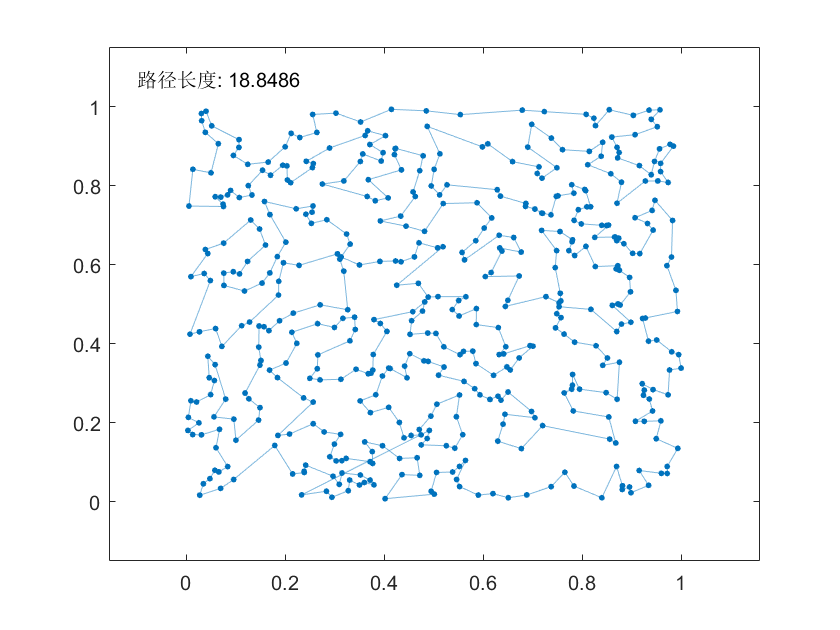

dist = calc_dist(sortedCities');
% clf;
% plot_trajectory(sortedCities');
% axis([-0.2, 1.2, -0.2, 1.2]);
% hold on;
% text(0.1, 0.8, {['距离: ', num2str(dist)]});
clf;
test_graph = graph(1:501, [2:501, 1]);
plot(test_graph, 'XData',sortedCities(:,1), 'YData',sortedCities(:,2), "LineStyle","-", 'NodeLabel',{});
hold on;
text(-0.1, 1.07, {['路径长度: ', num2str(dist)]});

## 使用模拟退火法求解500城市问题

load x500.mat;

temprature = 1e8;
temprature_min = 1e-16;
episodes = 1e2;
episode_length = 1e8;
multi_swap = 2;
trajectory_old = cityXY;
tic;
[trajectory_new, dist, temprature, exit_flag] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
toc;

时间已过 133.152545 秒。


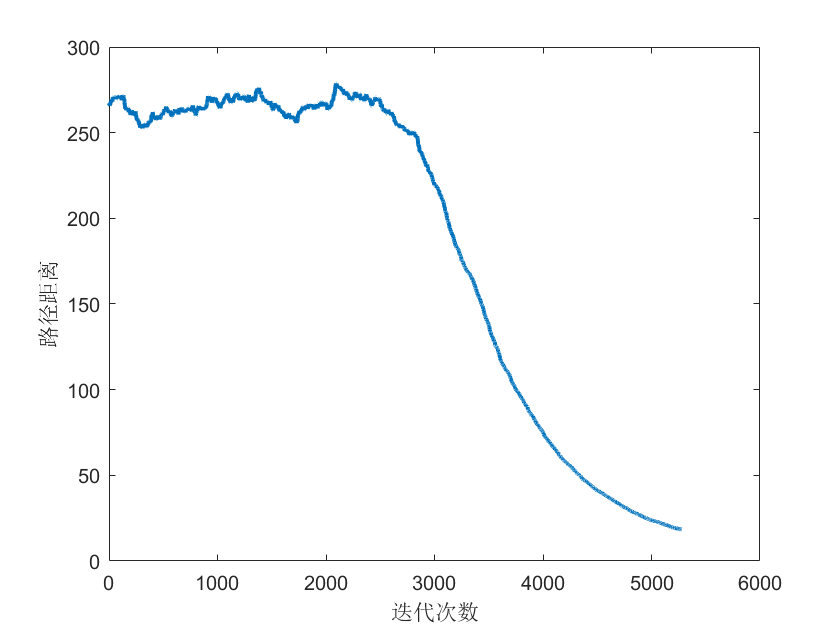

clf;
plot(dist, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('路径距离');

save("500_results.mat", "trajectory_new");


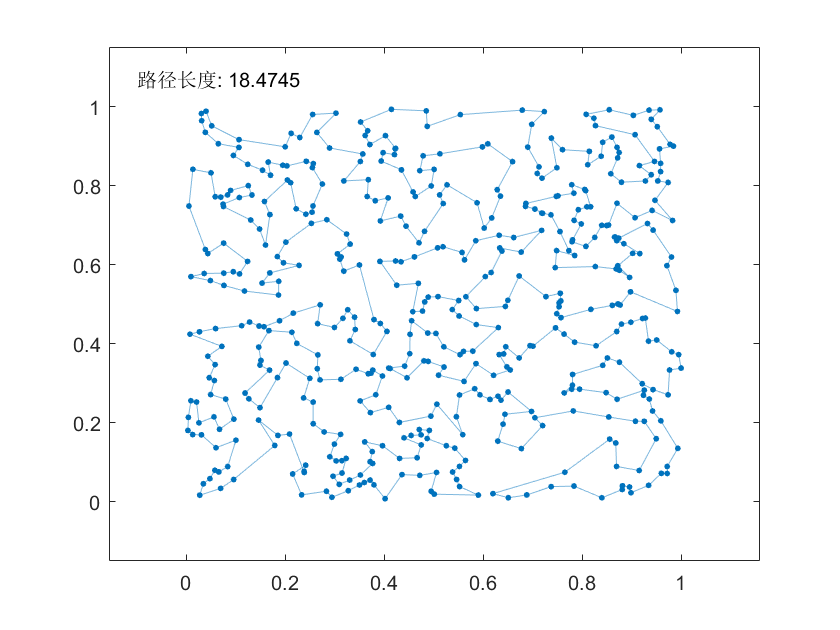

load('500_results.mat');
clf;
test_graph = graph(1:501, [2:501, 1]);
plot(test_graph, 'XData',trajectory_new(1,:), 'YData',trajectory_new(2,:), "LineStyle","-", 'NodeLabel',{});
hold on;
text(-0.1, 1.07, ["路径长度: " + num2str(dist(end))]);